# SBT_CW.mat Data Cleaning

Simple Box Test, Clock Wise

David Olson

04 Sep 2021

% Start Fresh
close all
clear all
clc

% Define Constants
Fs = 50; % Hz - confirmed via hand-written notes
dt = 1 / Fs;
init_time = 12; % Time spent sitting still before test for initialization

% Load Raw Data
load("SBT_CW_raw.mat")

## Accelerometer Data Cleaning

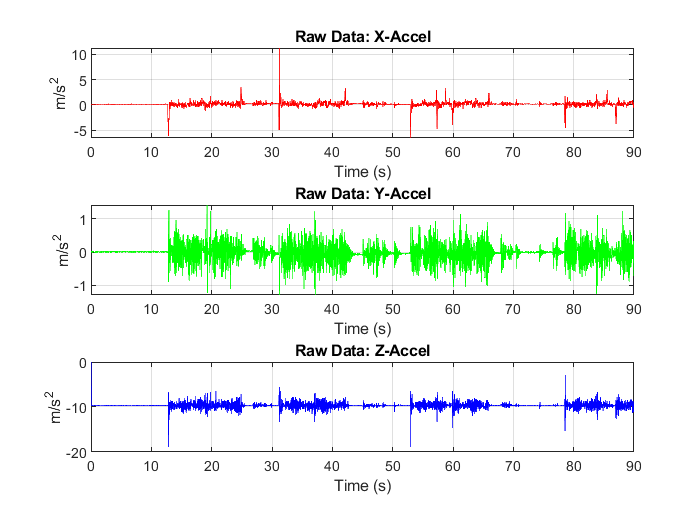

% Plot Data to see how it looks
figure(1)
subplot(3,1,1)
plot(t, accel(:,1), 'r')
title('Raw Data: X-Accel')
xlabel('Time (s)')
ylabel('m/s^2')
grid on
subplot(3,1,2)
plot(t, accel(:,2), 'g')
title('Raw Data: Y-Accel')
xlabel('Time (s)')
ylabel('m/s^2')
grid on
subplot(3,1,3)
plot(t, accel(:,3), 'b')
title('Raw Data: Z-Accel')
xlabel('Time (s)')
ylabel('m/s^2')
grid on

**Data looks good, no need for adjustment**

## Gyroscope Data Cleaning

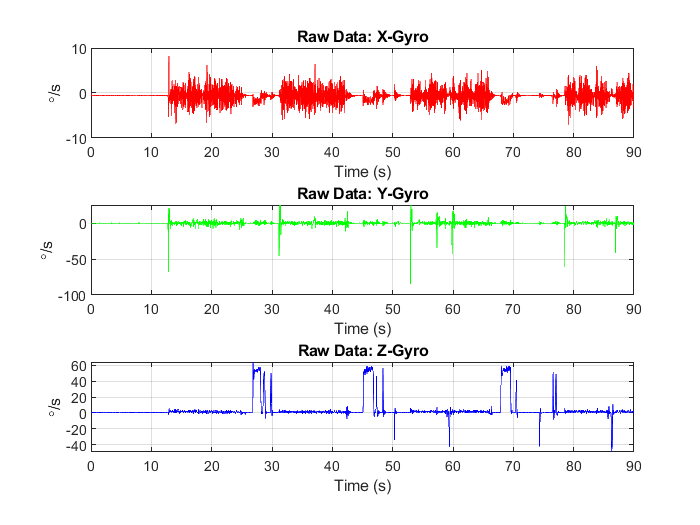

% Plot Data to see how it looks
figure(2)
subplot(3,1,1)
plot(t, gyro(:,1) * 180/pi, 'r')
title('Raw Data: X-Gyro')
xlabel('Time (s)')
ylabel('\circ/s')
grid on
subplot(3,1,2)
plot(t, gyro(:,2) * 180/pi, 'g')
title('Raw Data: Y-Gyro')
xlabel('Time (s)')
ylabel('\circ/s')
grid on
subplot(3,1,3)
plot(t, gyro(:,3) * 180/pi, 'b')
title('Raw Data: Z-Gyro')
xlabel('Time (s)')
ylabel('\circ/s')
grid on

**Data looks good, no need for adjustment**

Y-gyro spikes hard as expected with tilt from the robot

## Odometry Data Cleaning

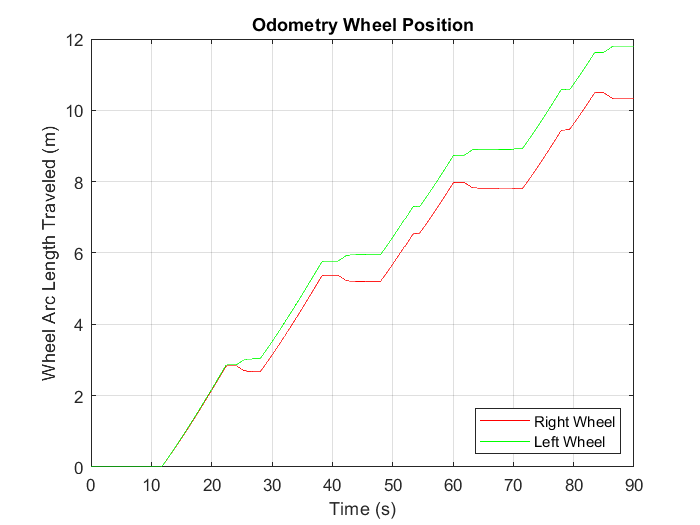

figure(3)
plot(t, odo(:,1), 'r', t, odo(:,2), 'g')
title('Odometry Wheel Position')
xlabel('Time (s)')
ylabel('Wheel Arc Length Traveled (m)')
legend('Right Wheel', 'Left Wheel', 'Location', "SouthEast")
grid on

**Data looks good, no need for adjustment**

## **Depth Camera Data Cleaning**

   
% Pre-Allocate
[kinect_samples, ~] = size(depth);
numPoints = 5000;
xyz = zeros(3, numPoints, kinect_samples);

% Convert to XYZ with down-sampling
tic
for k = 2 : kinect_samples
    xyz(:,:,k) = depth2xyz(depth, numPoints, k);
end
toc

Elapsed time is 8.070012 seconds.


## Depth Camera Animation

% % Show Animation
% for k = 2 : kinect_samples
%     
%     figure
%     hold on
%     plot3(xyz(1,:,k), xyz(2,:,k), xyz(3,:,k), 'b.');
%     viscircles([0,0], 0.35, 'Color', 'k');
%     quiver3(0,0,0,0.5,0,0, 'Color', 'r', 'LineWidth', 3);
%     title(['Kinect Point Cloud:   t = ', num2str(k)])
%     xlabel('X (m)')
%     ylabel('Y (m)')
%     zlabel('Z (m)')
%     xlim([-0.5 3.5])
%     
%     axis equal
%     view([-156.521 13.341])
%     grid on
%     hold off
%     
% %     pause(1)
%     
% %     dummy = input('Hit Enter to Move to Next Frame, Hit Q to Quit:  ', "s");
% %     if (dummy == 'Q')
% %         break
% %     end
% %     clf(4)
% %     clc
%     
% end

% Establish Point Cloud Processing Parameters
[~, K, num_frames] = size(xyz);

% Convert 3D Matrix into Cell Array
new_xyz = cell(num_frames,1);
for n = 1 : num_frames
    new_xyz{n} = xyz(:,:,n);
end
xyz = new_xyz;

## Separate Point Cloud Data into Wall and Floor Points

% Define Thresholds
x_thres = 1.5;
z_thres = 0;

% Separate Points
xyz_wall = cell(num_frames,1);
xyz_floor = cell(num_frames,1);

for n = 2 : num_frames
    
    % Remove all {0;0;0] measurements
    zero_mask = logical(sum(xyz{n}) ~= 0);
    xyz{n} = xyz{n}(:,zero_mask);
    
    % Locate and Store floor points
    floor_mask = (xyz{n}(1,:) < x_thres) & (xyz{n}(3,:) < z_thres);
    xyz_floor{n} = xyz{n}(:,floor_mask);
    
    % Locate and Store wall points
    wall_mask = (xyz{n}(3,:) >= z_thres);
    xyz_wall{n} = xyz{n}(:,wall_mask);
    
end

% - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - -
% Test Thresholding
test_point_cloud_flag = false;

if (test_point_cloud_flag == true)
    test_frame = 22;
    plot_point_cloud(xyz{test_frame}, ['Full Point Cloud at t = ', num2str(test_frame), 's'])
    plot_point_cloud(xyz_wall{test_frame}, ['Wall Only Point Cloud at t = ', num2str(test_frame), 's'])
    plot_point_cloud(xyz_floor{test_frame}, ['Floor Only Point Cloud at t = ', num2str(test_frame), 's'])
end

## Verify the attitude of the floor with a quick test case

% % Verify Good Floor Data
% test_frame = 22;
% plot_point_cloud(xyz_floor{test_frame}, ['Floor Only Point Cloud at t = ', num2str(test_frame), 's'])
% % Pitch of two Example Points
% atan2(-0.03661 - -0.03142, 1.316 - 0.4602) * 180/pi
% % Accomplish Crude Prediction of "Ground Truth" Pitch Values
% pitch = zeros(1, num_frames);
% for n = 2 : num_frames
%     
%     % Grab and Average All Points between x = 0.5 & x = 0.6
%     xyz_floor_back_mask = (xyz_floor{n}(1,:) > 0.5) & (xyz_floor{n}(1,:) < 0.6);
%     xyz_back_avg = mean(xyz_floor{n}(:,xyz_floor_back_mask)')';
%     
%     % Grab and Average All Points between x = 0.9 & x = 0.1
%     xyz_floor_front_mask = (xyz_floor{n}(1,:) > 0.9) & (xyz_floor{n}(1,:) < 1);
%     xyz_front_avg = mean(xyz_floor{n}(:,xyz_floor_front_mask)')';
%     
%     pitch(n) = atan2(xyz_front_avg(3) - xyz_back_avg(3), xyz_front_avg(1) - xyz_back_avg(1));
%     
% end
% 
% % Plot "Ground Truth" Estimate of Pitch
% plot(2:num_frames, pitch(2:end) * 180/pi, 'g*')
% title('"Ground Truth" Pitch Guesses')
% xlabel('Frames')
% xlim([2 num_frames])
% ylabel('Pitch (\circ)')
% grid on

## Shift Wall and Floor Point Clouds to the Origin

% Locate and Shift each floor point cloud to the origin
% for n = 2 : num_frames
% %     x_max = max(xyz_floor{n}(1,:));
% %     x_min = min(xyz_floor{n}(1,:));
% %     x_shift = x_min + ((x_max - x_min)/2);
% %     y_max = max(xyz_floor{n}(2,:));
% %     y_min = min(xyz_floor{n}(2,:));
% %     y_shift = y_min + ((y_max - y_min)/2);
%     xyz_floor{n} = xyz_floor{n} - [0.5; 0; 0];
% end
% 
% Locate and Shift each wall point cloud to the origin
for n = 2 : num_frames
    x_max = max(xyz_wall{n}(1,:));
    x_min = min(xyz_wall{n}(1,:));
    x_shift = x_min + ((x_max - x_min)/2);
    xyz_wall{n} = xyz_wall{n} - [x_shift; 0; 0];
end

% - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - -
% Test Point Cloud Shifting
test_point_cloud_flag = false;

if (test_point_cloud_flag == true)
    test_frame = 22;
    plot_point_cloud(xyz_wall{test_frame}, ['Wall Only Point Cloud at t = ', num2str(test_frame), 's'])
    hold on
    plot_point_cloud(xyz_floor{test_frame}, ['Floor Only Point Cloud at t = ', num2str(test_frame), 's'])
%     quiver3(0,0,0,cos(3*pi/180),0,sin(3*pi/180))
    hold off
end

## Complete the SNHT Floor Search

Searching for pitch only!

Begin Processing Frame #2

Elapsed time is 1.323298 seconds.


Begin Processing Frame #3

Elapsed time is 1.354936 seconds.


Begin Processing Frame #4

Elapsed time is 1.358304 seconds.


Begin Processing Frame #5

Elapsed time is 1.332540 seconds.


Begin Processing Frame #6

Elapsed time is 1.324895 seconds.


Begin Processing Frame #7

Elapsed time is 1.343906 seconds.


Begin Processing Frame #8

Elapsed time is 1.365935 seconds.


Begin Processing Frame #9

Elapsed time is 1.295867 seconds.


Begin Processing Frame #10

Elapsed time is 1.364518 seconds.


Begin Processing Frame #11

Elapsed time is 1.292932 seconds.


Begin Processing Frame #12

Elapsed time is 1.356988 seconds.


Begin Processing Frame #13

Elapsed time is 1.349885 seconds.


Begin Processing Frame #14

Elapsed time is 1.315146 seconds.


Begin Processing Frame #15

Elapsed time is 1.326072 seconds.


Begin Processing Frame #16

Elapsed time is 1.312445 seconds.


Begin Processing Frame #17

Elapsed time is 1.070553 seconds.


Begin Processing Frame #18

Elapsed time is 1.074372 seconds.


Begin Processing Frame #19

Elapsed time is 1.056671 seconds.


Begin Processing Frame #20

Elapsed time is 1.066481 seconds.


Begin Processing Frame #21

Elapsed time is 0.999801 seconds.


Begin Processing Frame #22

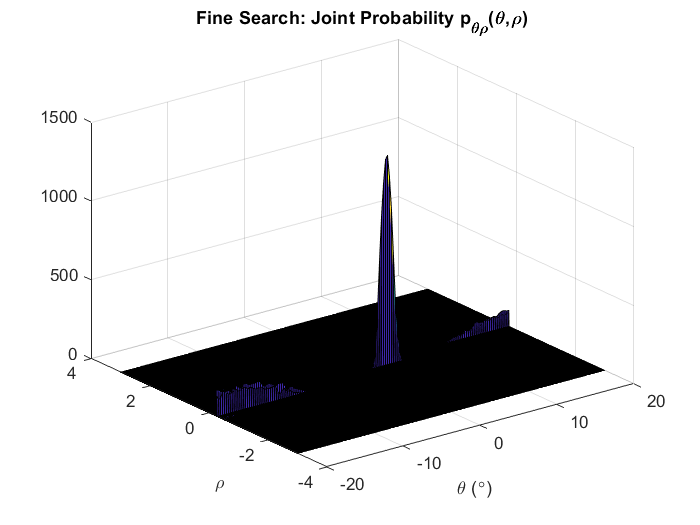

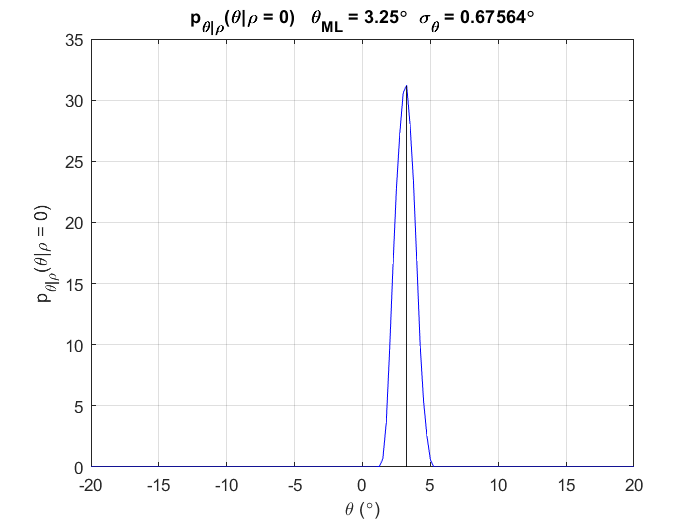

Elapsed time is 1.148905 seconds.


Begin Processing Frame #23

Elapsed time is 0.942285 seconds.


Begin Processing Frame #24

Elapsed time is 0.845988 seconds.


Begin Processing Frame #25

Elapsed time is 0.753430 seconds.


Begin Processing Frame #26

Elapsed time is 0.626028 seconds.


Begin Processing Frame #27

Elapsed time is 0.990416 seconds.


Begin Processing Frame #28

Elapsed time is 1.258382 seconds.


Begin Processing Frame #29

Elapsed time is 1.275922 seconds.


Begin Processing Frame #30

Elapsed time is 1.299002 seconds.


Begin Processing Frame #31

Elapsed time is 1.274638 seconds.


Begin Processing Frame #32

Elapsed time is 1.266971 seconds.


Begin Processing Frame #33

Elapsed time is 1.011518 seconds.


Begin Processing Frame #34

Elapsed time is 1.023830 seconds.


Begin Processing Frame #35

Elapsed time is 1.014284 seconds.


Begin Processing Frame #36

Elapsed time is 1.029823 seconds.


Begin Processing Frame #37

Elapsed time is 0.987566 seconds.


Begin Processing Frame #38

Elapsed time is 0.957410 seconds.


Begin Processing Frame #39

Elapsed time is 0.993545 seconds.


Begin Processing Frame #40

Elapsed time is 0.884766 seconds.


Begin Processing Frame #41

Elapsed time is 0.816812 seconds.


Begin Processing Frame #42

Elapsed time is 0.761918 seconds.


Begin Processing Frame #43

Elapsed time is 0.877040 seconds.


Begin Processing Frame #44

Elapsed time is 1.065913 seconds.


Begin Processing Frame #45

Elapsed time is 1.289927 seconds.


Begin Processing Frame #46

Elapsed time is 1.359934 seconds.


Begin Processing Frame #47

Elapsed time is 1.356004 seconds.


Begin Processing Frame #48

Elapsed time is 1.277535 seconds.


Begin Processing Frame #49

Elapsed time is 1.307273 seconds.


Begin Processing Frame #50

Elapsed time is 0.308893 seconds.


Begin Processing Frame #51

Elapsed time is 1.309903 seconds.


Begin Processing Frame #52

Elapsed time is 1.338234 seconds.


Begin Processing Frame #53

Elapsed time is 1.082249 seconds.


Begin Processing Frame #54

Elapsed time is 1.062230 seconds.


Begin Processing Frame #55

Elapsed time is 1.027775 seconds.


Begin Processing Frame #56

Elapsed time is 1.075774 seconds.


Begin Processing Frame #57

Elapsed time is 1.046459 seconds.


Begin Processing Frame #58

Elapsed time is 0.991047 seconds.


Begin Processing Frame #59

Elapsed time is 0.952372 seconds.


Begin Processing Frame #60

Elapsed time is 0.868790 seconds.


Begin Processing Frame #61

Elapsed time is 0.914465 seconds.


Begin Processing Frame #62

Elapsed time is 0.813714 seconds.


Begin Processing Frame #63

Elapsed time is 0.685344 seconds.


Begin Processing Frame #64

Elapsed time is 0.823398 seconds.


Begin Processing Frame #65

Elapsed time is 1.094884 seconds.


Begin Processing Frame #66

Elapsed time is 1.225592 seconds.


Begin Processing Frame #67

Elapsed time is 1.260487 seconds.


Begin Processing Frame #68

Elapsed time is 1.283292 seconds.


Begin Processing Frame #69

Elapsed time is 1.290998 seconds.


Begin Processing Frame #70

Elapsed time is 1.226154 seconds.


Begin Processing Frame #71

Elapsed time is 1.232581 seconds.


Begin Processing Frame #72

Elapsed time is 1.283343 seconds.


Begin Processing Frame #73

Elapsed time is 1.375028 seconds.


Begin Processing Frame #74

Elapsed time is 1.363368 seconds.


Begin Processing Frame #75

Elapsed time is 1.389876 seconds.


Begin Processing Frame #76

Elapsed time is 1.067792 seconds.


Begin Processing Frame #77

Elapsed time is 1.052361 seconds.


Begin Processing Frame #78

Elapsed time is 1.006447 seconds.


Begin Processing Frame #79

Elapsed time is 1.013354 seconds.


Begin Processing Frame #80

Elapsed time is 0.979232 seconds.


Begin Processing Frame #81

Elapsed time is 0.914103 seconds.


Begin Processing Frame #82

Elapsed time is 0.941531 seconds.


Begin Processing Frame #83

Elapsed time is 0.919202 seconds.


Begin Processing Frame #84

Elapsed time is 0.950198 seconds.


Begin Processing Frame #85

Elapsed time is 0.850326 seconds.


Begin Processing Frame #86

Elapsed time is 0.702593 seconds.


Begin Processing Frame #87

Elapsed time is 0.788269 seconds.


Begin Processing Frame #88

Elapsed time is 1.055657 seconds.


Begin Processing Frame #89

Elapsed time is 1.329383 seconds.


Begin Processing Frame #90

Elapsed time is 1.322506 seconds.


Begin Processing Frame #91

Elapsed time is 1.340000 seconds.


% Pre-Allocate Memory
theta_meas = zeros(1,91);
theta_sigmas = zeros(1,91);

% Run SNHT pitch algorithm
test_frame = 22;
for n = 2 : num_frames
    
    % Select Test Frame to Plot
    if (n == test_frame)
        plot_flag = true;
    else
        plot_flag = false;
    end
    
    % Run SNHT Pitch
    fprintf(['Begin Processing Frame #', num2str(n)])
    tic 
    [theta_meas(n), theta_sigmas(n)] = SNHT_pitch(xyz_floor{n}, plot_flag);
    toc
    
end

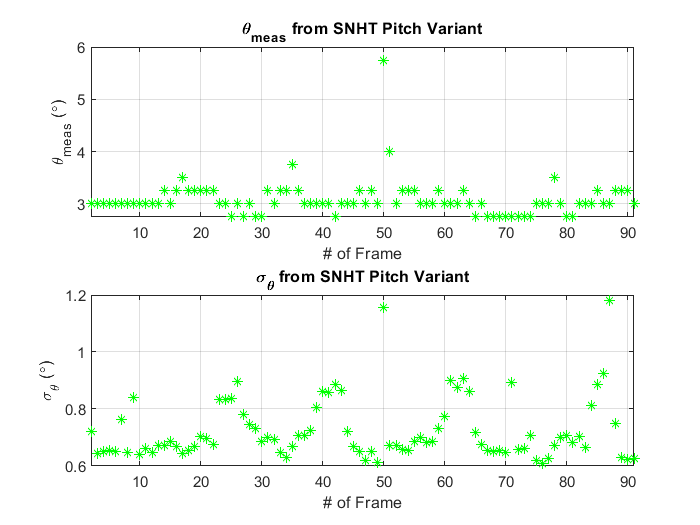

% Plot Results
figure
subplot(2,1,1)
plot(1:num_frames, theta_meas * 180/pi, 'g*')
title('\theta_m_e_a_s from SNHT Pitch Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\theta_m_e_a_s (\circ)')
grid on
subplot(2,1,2)
plot(1:num_frames, theta_sigmas * 180/pi, 'g*')
title('\sigma_\theta from SNHT Pitch Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\sigma_\theta (\circ)')
grid on

## Process Wall Point Clouds

Begin Processing Frame #2

Elapsed time is 1.163154 seconds.


Begin Processing Frame #3

Elapsed time is 1.066801 seconds.


Begin Processing Frame #4

Elapsed time is 1.110945 seconds.


Begin Processing Frame #5

Elapsed time is 1.020495 seconds.


Begin Processing Frame #6

Elapsed time is 1.073815 seconds.


Begin Processing Frame #7

Elapsed time is 0.979348 seconds.


Begin Processing Frame #8

Elapsed time is 1.016296 seconds.


Begin Processing Frame #9

Elapsed time is 0.857074 seconds.


Begin Processing Frame #10

Elapsed time is 1.012274 seconds.


Begin Processing Frame #11

Elapsed time is 1.059079 seconds.


Begin Processing Frame #12

Elapsed time is 1.076724 seconds.


Begin Processing Frame #13

Elapsed time is 1.147967 seconds.


Begin Processing Frame #14

Elapsed time is 0.905558 seconds.


Begin Processing Frame #15

Elapsed time is 0.915335 seconds.


Begin Processing Frame #16

Elapsed time is 0.928963 seconds.


Begin Processing Frame #17

Elapsed time is 2.233293 seconds.


Begin Processing Frame #18

Elapsed time is 2.248886 seconds.


Begin Processing Frame #19

Elapsed time is 2.369046 seconds.


Begin Processing Frame #20

Elapsed time is 2.609172 seconds.


Begin Processing Frame #21

Elapsed time is 2.923451 seconds.


Begin Processing Frame #22

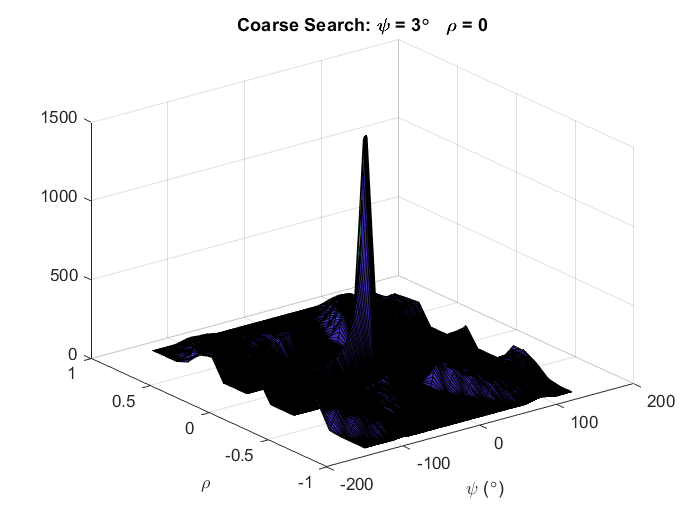

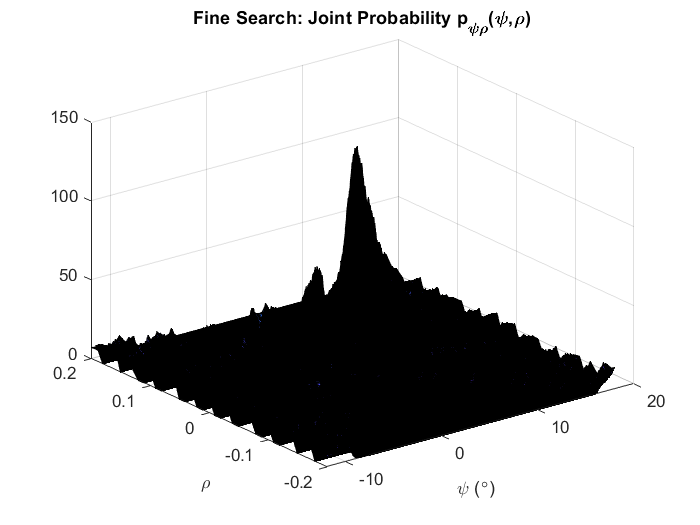

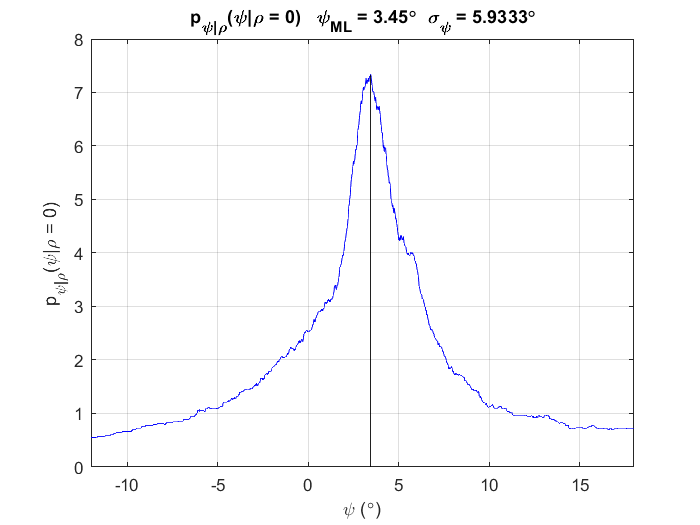

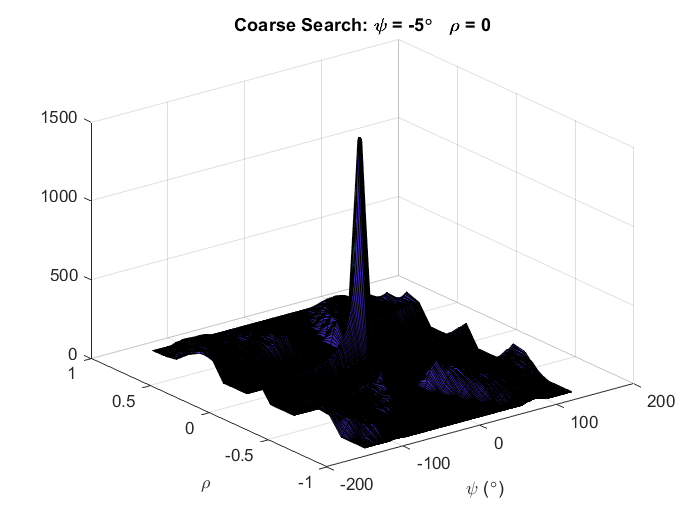

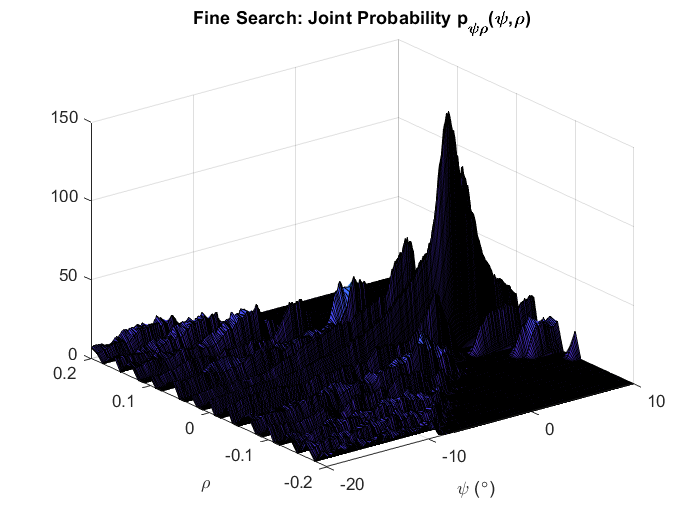

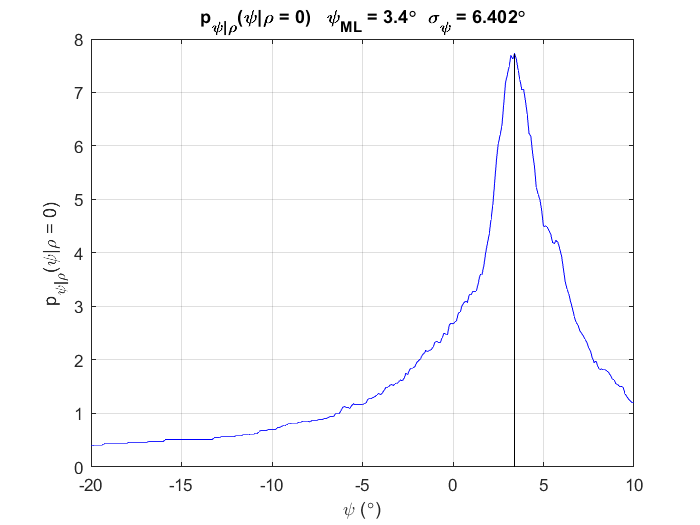

Elapsed time is 3.771581 seconds.


Begin Processing Frame #23

Elapsed time is 3.877713 seconds.


Begin Processing Frame #24

Elapsed time is 4.649541 seconds.


Begin Processing Frame #25

Elapsed time is 5.608743 seconds.


Begin Processing Frame #26

Elapsed time is 6.703998 seconds.


Begin Processing Frame #27

Elapsed time is 3.146997 seconds.


Begin Processing Frame #28

Elapsed time is 1.161800 seconds.


Begin Processing Frame #29

Elapsed time is 0.631602 seconds.


Begin Processing Frame #30

Elapsed time is 1.021030 seconds.


Begin Processing Frame #31

Elapsed time is 0.639556 seconds.


Begin Processing Frame #32

Elapsed time is 0.892488 seconds.


Begin Processing Frame #33

Elapsed time is 2.118447 seconds.


Begin Processing Frame #34

Elapsed time is 2.567858 seconds.


Begin Processing Frame #35

Elapsed time is 2.241707 seconds.


Begin Processing Frame #36

Elapsed time is 2.577758 seconds.


Begin Processing Frame #37

Elapsed time is 2.668704 seconds.


Begin Processing Frame #38

Elapsed time is 3.039848 seconds.


Begin Processing Frame #39

Elapsed time is 3.556182 seconds.


Begin Processing Frame #40

Elapsed time is 4.368024 seconds.


Begin Processing Frame #41

Elapsed time is 5.102874 seconds.


Begin Processing Frame #42

Elapsed time is 5.442691 seconds.


Begin Processing Frame #43

Elapsed time is 4.640660 seconds.


Begin Processing Frame #44

Elapsed time is 2.441215 seconds.


Begin Processing Frame #45

Elapsed time is 0.661137 seconds.


Begin Processing Frame #46

Elapsed time is 0.247481 seconds.


Begin Processing Frame #47

Elapsed time is 0.402782 seconds.


Begin Processing Frame #48

Elapsed time is 0.546621 seconds.


Begin Processing Frame #49

Elapsed time is 0.562037 seconds.


Begin Processing Frame #50

Elapsed time is 4.594349 seconds.


Begin Processing Frame #51

Elapsed time is 0.426570 seconds.


Begin Processing Frame #52

Elapsed time is 0.370576 seconds.


Begin Processing Frame #53

Elapsed time is 1.979726 seconds.


Begin Processing Frame #54

Elapsed time is 2.242522 seconds.


Begin Processing Frame #55

Elapsed time is 2.289626 seconds.


Begin Processing Frame #56

Elapsed time is 2.482313 seconds.


Begin Processing Frame #57

Elapsed time is 2.677701 seconds.


Begin Processing Frame #58

Elapsed time is 2.878044 seconds.


Begin Processing Frame #59

Elapsed time is 3.054365 seconds.


Begin Processing Frame #60

Elapsed time is 3.655840 seconds.


Begin Processing Frame #61

Elapsed time is 4.293845 seconds.


Begin Processing Frame #62

Elapsed time is 5.209132 seconds.


Begin Processing Frame #63

Elapsed time is 6.075354 seconds.


Begin Processing Frame #64

Elapsed time is 5.170605 seconds.


Begin Processing Frame #65

Elapsed time is 2.529597 seconds.


Begin Processing Frame #66

Elapsed time is 1.380532 seconds.


Begin Processing Frame #67

Elapsed time is 1.215217 seconds.


Begin Processing Frame #68

Elapsed time is 1.068889 seconds.


Begin Processing Frame #69

Elapsed time is 1.164059 seconds.


Begin Processing Frame #70

Elapsed time is 1.367139 seconds.


Begin Processing Frame #71

Elapsed time is 1.434627 seconds.


Begin Processing Frame #72

Elapsed time is 1.115946 seconds.


Begin Processing Frame #73

Elapsed time is 0.548050 seconds.


Begin Processing Frame #74

Elapsed time is 0.377335 seconds.


Begin Processing Frame #75

Elapsed time is 0.232297 seconds.


Begin Processing Frame #76

Elapsed time is 2.296935 seconds.


Begin Processing Frame #77

Elapsed time is 2.389020 seconds.


Begin Processing Frame #78

Elapsed time is 2.530519 seconds.


Begin Processing Frame #79

Elapsed time is 2.579577 seconds.


Begin Processing Frame #80

Elapsed time is 2.816051 seconds.


Begin Processing Frame #81

Elapsed time is 3.109625 seconds.


Begin Processing Frame #82

Elapsed time is 3.014477 seconds.


Begin Processing Frame #83

Elapsed time is 3.415661 seconds.


Begin Processing Frame #84

Elapsed time is 4.086306 seconds.


Begin Processing Frame #85

Elapsed time is 4.694020 seconds.


Begin Processing Frame #86

Elapsed time is 5.639113 seconds.


Begin Processing Frame #87

Elapsed time is 5.328604 seconds.


Begin Processing Frame #88

Elapsed time is 2.917622 seconds.


Begin Processing Frame #89

Elapsed time is 0.636042 seconds.


Begin Processing Frame #90

Elapsed time is 0.574688 seconds.


Begin Processing Frame #91

Elapsed time is 0.593306 seconds.


% Pre-Allocate Memory
psi_fw_meas = zeros(1,91);
psi_fw_sigmas = zeros(1,91);
psi_sw_meas = zeros(1,91);
psi_sw_sigmas = zeros(1,91);

% Run SNHT pitch algorithm
test_frame = 22;
for n = 2 : num_frames
    
    % Select Test Frame to Plot
    if (n == test_frame)
        plot_flag = true;
    else
        plot_flag = false;
    end
    
    % Run SNHT Pitch
    fprintf(['Begin Processing Frame #', num2str(n)])
    tic 
    [psi_fw_meas(n), psi_fw_sigmas(n)] = SNHT_front_wall(xyz_wall{n}, plot_flag);
    [psi_sw_meas(n), psi_sw_sigmas(n)] = SNHT_side_wall(xyz_wall{n}, plot_flag);
    toc
    
end

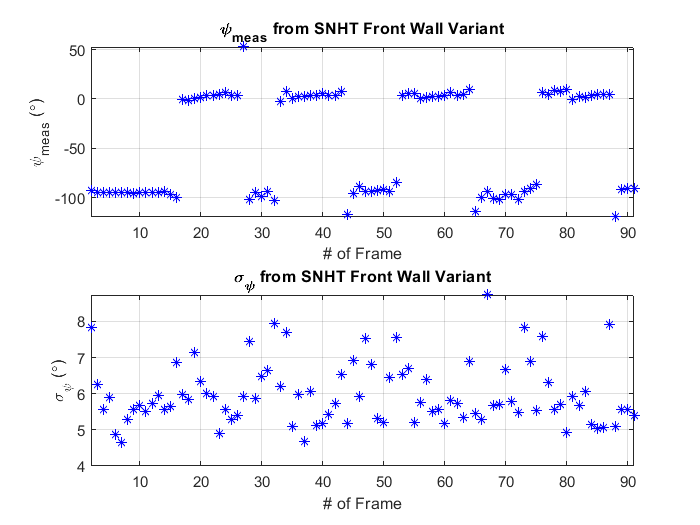

% Plot Results
figure
subplot(2,1,1)
plot(1:num_frames, psi_fw_meas * 180/pi, 'b*')
title('\psi_m_e_a_s from SNHT Front Wall Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\psi_m_e_a_s (\circ)')
grid on
subplot(2,1,2)
plot(1:num_frames, psi_fw_sigmas * 180/pi, 'b*')
title('\sigma_\psi from SNHT Front Wall Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\sigma_\psi (\circ)')
grid on

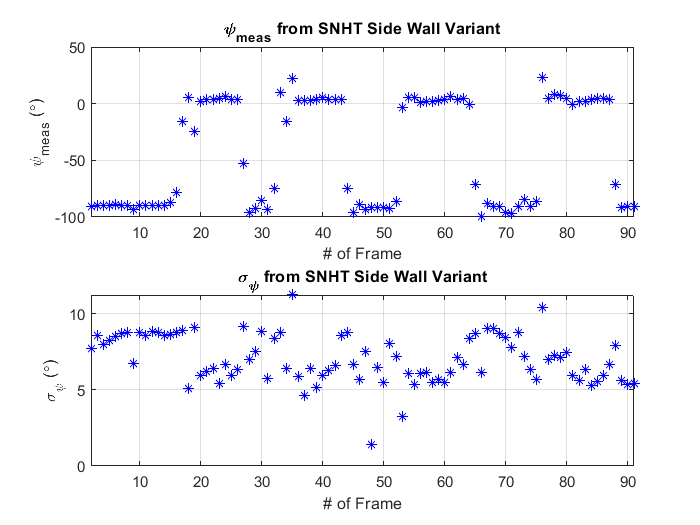

figure
subplot(2,1,1)
plot(1:num_frames, psi_sw_meas * 180/pi, 'b*')
title('\psi_m_e_a_s from SNHT Side Wall Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\psi_m_e_a_s (\circ)')
grid on
subplot(2,1,2)
plot(1:num_frames, psi_sw_sigmas * 180/pi, 'b*')
title('\sigma_\psi from SNHT Side Wall Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\sigma_\psi (\circ)')
grid on

## Save Data

% Transpose Everything to the Same Format
t = t';
accel = accel';
gyro = gyro';
odo = odo';

save("SBT_CW.mat", ...
     "Fs", "dt", "init_time", ...
     "t", "accel", "gyro", "odo", ...
     'theta_meas', 'theta_sigmas', ...
     'psi_fw_meas', 'psi_fw_sigmas', ...
     'psi_sw_meas', 'psi_sw_sigmas')